%https://uk.mathworks.com/matlabcentral/fileexchange/74545-generalized-seir-epidemic-model-fitting-and-computation?s_tid=LandingPageTabfx
%https://github.com/ECheynet/SEIR
%https://github.com/CSSEGISandData/COVID-19


Use the readtable function to load the data set covid.csv

Plot China (Hubei), UK, Italy, USA (New York)

Using logarithmic plots

Select the different provinces from China and compare the number of evolution of the number of confirmed cases for the different regions

Select different regions for Europe (France, Italy, Spain Germany, UK ) and compare the time evolution for the number of compared cases

Place thes plots on a plot array hint using the subplot command

indLocation = find(contains(tableRecovered.ProvinceState,'Hubei')==1)

Recovered = table2array(tableRecovered(indLocation,5:end));

Deaths = table2array(tableDeaths(indLocation,5:end));

Confirmed = table2array(tableConfirmed(indLocation,5:end));

Use the websave command to download the data from

note

status = {'Confirmed','Deaths','Recovered'};

     url = ['https://raw.githubusercontent.com/CSSEGISandData/COVID-19/master/csse_covid_19_data/csse_covid_19_time_series/time_series_19-covid-',status{ii},'.csv'];

use filename="myout.csv" to store the read data

outfilename = websave(filename,url)

data=readtable('../data/mtcars.csv')

Plot a 2x2 subplot array illustrating the relationship between mpg and the properties cyl, disp, wt and hp

experiment with mean median and mode which variables exhibit the greatest difference between these values


histogram(data.hp)
histogram(data.wt)





pdhp = fitdist(data.hp,'Normal')

pdhp =   NormalDistribution

  Normal distribution
       mu = 146.688   [121.968, 171.407]
    sigma = 68.5629   [54.9671, 91.1529]


x_values = 0:0.01:6;
y = 16*pdf(pdwt,x_values)/0.45;
plot(x_values,y,'LineWidth',2)
hold on
histogram(data.wt)

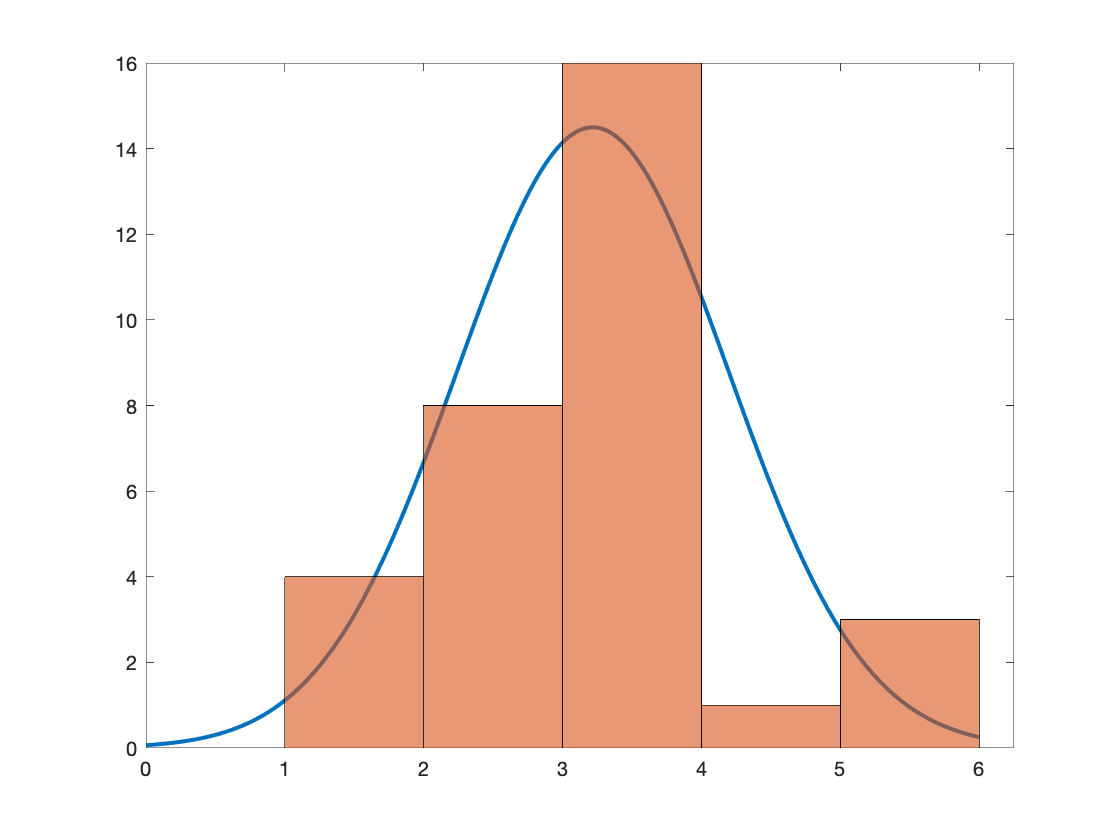

hold off


pdwt = fitdist(data.wt,'Normal')

pdwt =   NormalDistribution

  Normal distribution
       mu =  3.21725   [2.86448, 3.57002]
    sigma = 0.978457   [0.784433, 1.30084]


x_values = 0:2:400;

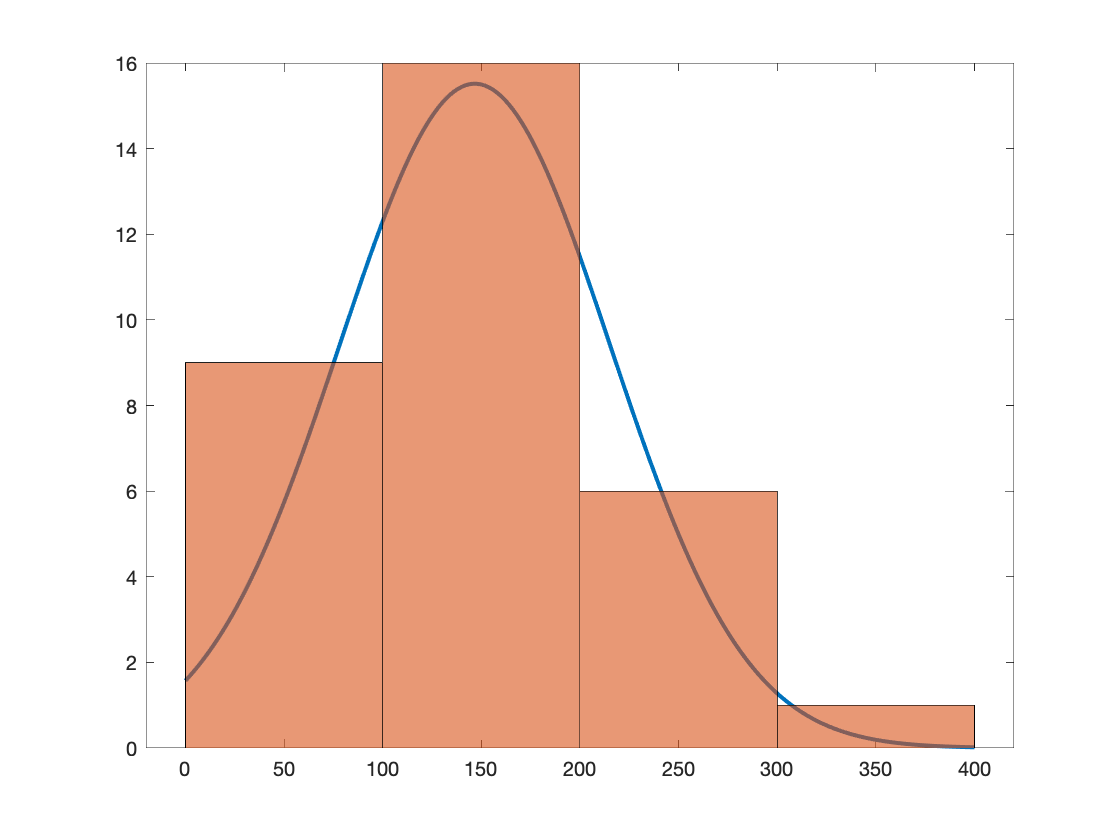

y = 16000*pdf(pdhp,x_values)/6;
plot(x_values,y,'LineWidth',2)
hold on
histogram(data.hp)
hold off

Use the least squareas method   to compute the best fit

Least squares method

[http://mathworld.wolfram.com/LeastSquaresFitting.html](http://mathworld.wolfram.com/LeastSquaresFitting.html)

xv=data.disp

xv =   160.0000
  160.0000
  108.0000
  258.0000
  360.0000
  225.0000
  360.0000
  146.7000
  140.8000
  167.6000


yv=data.mpg

yv =    21.0000
   21.0000
   22.8000
   21.4000
   18.7000
   18.1000
   14.3000
   24.4000
   22.8000
   19.2000


num=numel(xv);
xmean=mean(xv);
ymean=mean(yv);
sxx=sum(xv.*xv);
syy=sum(yv.*yv);
sx=sum(xv);
sy=sum(yv);

ssxx=sum((xv-xmean).*(xv-xmean));
ssyy=sum((yv-ymean).*(yv-ymean));

ssxy=sum((xv-xmean).*(yv-ymean));
b=ssxy/ssxx;

a=ymean-b*xmean;

corcoeff=ssxy.^2/(ssxx*ssyy);

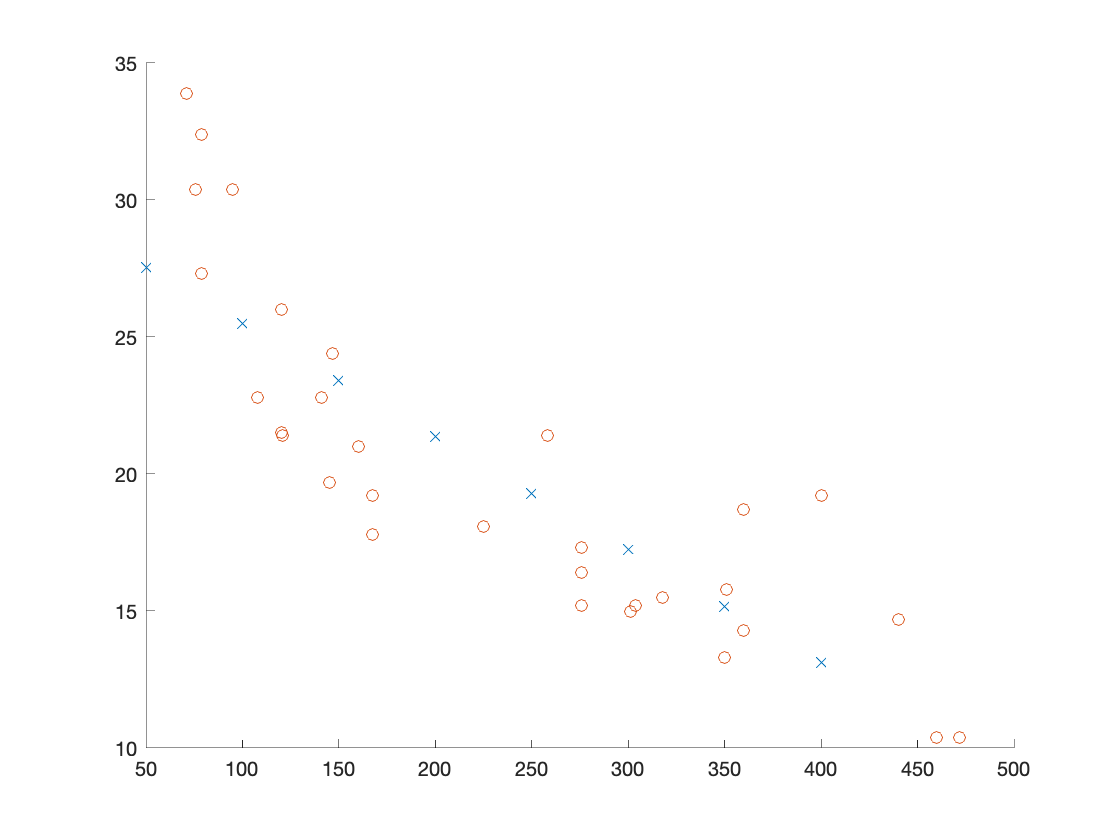

xtest=50:50:400;
ytest=b.*xtest+a;
figure
hold on
plot(xtest,ytest,'x');
plot(xv,yv,'o')
hold off